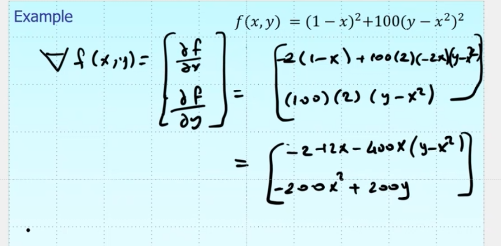

hesian matrix

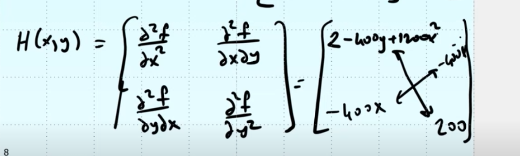

buraya x yerine 0 y yerine 0 yazılıyor.

hesaiyan matrixe x=0 y=0 yazılırsa  sonuç  aşağıdaki gibidir

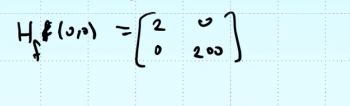

hesiyan matisinin tersine ihtiyacımız var köşegenler 0 olduğu için birşey değişmiyor.

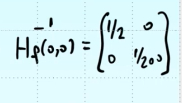

new estimated value for iteration

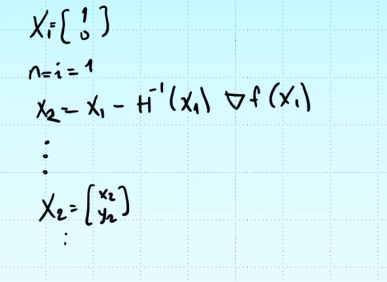

% Newton Algoritması
% Newton yöntemini uygulamak için bir fonksiyon

function [X, iterations, trajectory] = newton(X0, gradient, epsilon)
    iterations = 0; % Başlangıçta iterasyon sayısı 0
    max_iterations = 1000; % Maksimum iterasyon sayısı
    X = X0; % Başlangıç noktası
    trajectory = X; % Trajektoryayı başlangıç noktasıyla başlat

    % Newton yöntemi döngüsü
    while norm(gradient(X(1), X(2))) > epsilon && iterations < max_iterations
        % Hessian matrisi tanımlanıyor
        Hessian = [1200*X(1)^2 - 400*X(2) + 2, -400*X(1);
                   -400*X(1), 200];
        % X'in güncellenmesi (Newton adımı)
        X = X - inv(Hessian) * gradient(X(1), X(2));
        % Trajektoryaya yeni X değeri ekleniyor
        trajectory = [trajectory, X];
        % İterasyon sayısı artırılıyor
        iterations = iterations + 1;
    end
end


% Rosenbrock fonksiyonunu, türevini (gradient) ve Hessian'ını tanımlayın
f = @(x, y) (1 - x).^2 + 100*(y - x.^2).^2; % Rosenbrock fonksiyonu

gradient_rosenbrock = @(x, y) [ -2*(1 - x) - 400*x.*(y - x.^2);
                                200*(y - x.^2) ]; % Rosenbrock fonksiyonunun gradienti

% Newton yöntem fonksiyonunu çağır
X0 = [0; 0]; % Başlangıç tahmini
epsilon = 1e-6; % Yakınsama toleransı

[X_opt, iter_count, traj] = newton(X0, gradient_rosenbrock, epsilon);

% Sonucu görüntüle
disp('Optimized solution:');
disp(X_opt);
disp('Number of iterations:');
disp(iter_count);

% Optimizasyonun trajektoryasını görselleştir
[X1, Y1] = meshgrid(-2:0.1:2, -1:0.1:3); % Görselleştirme için bir grid oluştur
Z1 = (1 - X1).^2 + 100*(Y1 - X1.^2).^2;  % Rosenbrock fonksiyon değerlerini hesapla


figure;
contour(X1, Y1, Z1, 50); % Rosenbrock fonksiyonunun kontur grafiği
hold on;
plot(traj(1, :), traj(2, :), 'r-o', 'LineWidth', 2, 'MarkerFaceColor', 'r'); % Newton yönteminin trajektoryası
xlabel('x'); % x ekseni etiketi
ylabel('y'); % y ekseni etiketi
title('Trajectory of the Newton Optimization Process'); % Grafik başlığı
hold off;
